# Passive Dynamic Walker Simulation

clear;clc;

pdw.l1 = 2; pdw.l2 = 2;
pdw.m1 = 0.5; pdw.m2 = 0.5; pdw.mh = 0.5;

pdw.gamma = pi/30;
fps = 20;
deltat = 2;

% Requires manual tuning to make the PDW walk on the ramp. Needs some intuition
q0 = [0.15;-0.30;-1.2;2.4];

## Poincare's Map Fixed Point

options = optimset('TolFun',1e-12,'TolX',1e-12,'MaxIter',700,'MaxFunEvals',700,'Display','off');
[qopt,val,flag] = fsolve(@(qopt) stepdiff(qopt,deltat,pdw),q0,options);
if flag == 1
    disp('Successfully Converged.');
    q0 = qopt;
else
    disp('Failed to converge. Modify, IC or PDW parameters.')
end

Successfully Converged.


## Integrate

n = 1; % Number of steps
tstart = 0;
tsim = [];
qsim = [];

for k = 1:n
    [t,q,q0next] = one_step(tstart,deltat,q0,pdw);
%     tsim = [tsim; t(1:end-1,:)];
%     qsim = [qsim; q(1:end-1,:)];
    tsim = t;
    qsim = q;
end

## Animate

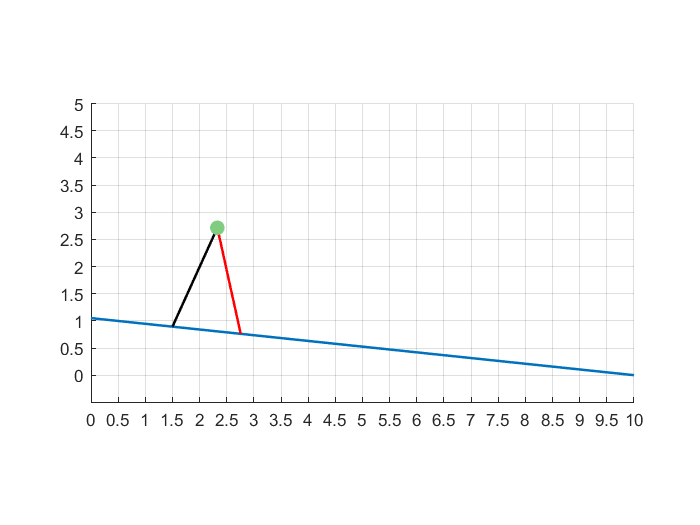

L = 10;
x = 1.5; 
y = (L-x)*tan(pdw.gamma);

figure(1);
grid on;
hold on;
for k=1:length(tsim)
    th1 = qsim(k,1); th2 = qsim(k,2);
    Ggh = [x - pdw.l1*(cos(pdw.gamma)*sin(th1) - cos(th1)*sin(pdw.gamma)); ...
        y + pdw.l1*(cos(pdw.gamma)*cos(th1) + sin(pdw.gamma)*sin(th1))];
    GgC2 = [x - pdw.l1*(cos(pdw.gamma)*sin(th1) - cos(th1)*sin(pdw.gamma)) + pdw.l2*(cos(th2)*(cos(pdw.gamma)*sin(th1) - cos(th1)*sin(pdw.gamma)) + sin(th2)*(cos(pdw.gamma)*cos(th1) + sin(pdw.gamma)*sin(th1))); ... 
        y + pdw.l1*(cos(pdw.gamma)*cos(th1) + sin(pdw.gamma)*sin(th1)) - pdw.l2*(cos(th2)*(cos(pdw.gamma)*cos(th1) + sin(pdw.gamma)*sin(th1)) - sin(th2)*(cos(pdw.gamma)*sin(th1) - cos(th1)*sin(pdw.gamma)))];
    
    line([0 L],[L*tan(pdw.gamma) 0],'LineWidth',1.5); % Ramp
    h1 = line([x Ggh(1)],[y Ggh(2)],'LineWidth',1.5,'Color','black'); % Stance Leg
    h2 = line([Ggh(1) GgC2(1)],[Ggh(2) GgC2(2)],'LineWidth',1.5,'Color','red'); % Swing Leg
    h3 = plot(Ggh(1),Ggh(2),'.','MarkerSize',30,'Color',[0.5 0.8 0.5]); % Hip
    axis([0 L -0.5 L/2]);
    xticks(0:0.5:L);
    yticks(0:0.5:L);
    daspect([1 1 1]);
    drawnow;
    
    % pause(0.5);
    if k ~= length(tsim)
        delete(h1);
        delete(h2);
        delete(h3);
    end
end